# TA1: Identificación

IDENTIFICACIÓN DEL SISTEMA: RESPUESTA AL ESCALÓN Y PRBS

s = tf('s');

## DATOS DE SIMULACIÓN DEL ESCALÓN

% Importar datos y guardarlos en vectores
datos_sim = readmatrix('datos_escalon_simulacion.DAT');

t_sim = datos_sim(:,1) - 3.006216984;
y_sim = datos_sim(:,2) - min(datos_sim(:,2));   % salida normalizada
u_sim = datos_sim(:,3) * (3/5);                 % entrada reescalada (el vector flag va de 1 a 5, lo modificamos para que sea de  0 a 3)

Ts_sim = mean(diff(t_sim)); % Tiepmo de muestreo

% Acá arreglamos errores en los datos de proteus
t_inicio = 0;
t_fin    = 6;
dt       = 0.001;

Npts = floor((t_fin - t_inicio)/dt);
i = 1;

Tt_sim = zeros(1, Npts);
u_sim_filt = zeros(1, Npts);
y_sim_filt = zeros(1, Npts);

for k = 1:Npts
    while (i < length(t_sim)) && (t_sim(i) < t_inicio + k*dt)
        i = i + 1;
    end
    Tt_sim(k) = (k-1)*dt;
    u_sim_filt(k) = u_sim(i);
    y_sim_filt(k) = y_sim(i);
end

u_sim_filt(1) = 0;

% Defino el objeto  para el system identification
data_sim_escalon = iddata(y_sim_filt', u_sim_filt', dt);

% Transferencia que escupe el system identification, 99% de coincidencia con
% la otra mitad de los datos

tf_6polos_escalon_simulacion = tf([1.158891170120908e+06] , [1,67.524408826597450,1.706768440587221e+03,2.303538442927073e+04,1.730485922460245e+05,6.943897404580413e+05,1.158357673009883e+06]);

% rlocus(tf_6polos_escalon_simulacion);
% title('ldr de la transferencia identificada con datos de la resuesta simulada al escalon');
% bode(tf_6polos_escalon_simulacion);
% title('bode de la transferencia identificada con datos de la respuesta simualda al escalon');



## DATOS MEDIDOS DEL ESCALÓN REAL

Importar datos, procesarlos:

% Importar datos y guardarlos en vectores
datos_escalon = readtable('datos_escalon_medido.CSV');

t_escalon = datos_escalon.Var4(4:end) + 3; % corrige offset
T_escalon = mean(diff(t_escalon));

y_escalon = datos_escalon.Var5(4:end);
y_escalon = y_escalon - mean(y_escalon(1:6000));   % elimina offset

% Filtro pasabajos para sacarle los pelos
fs = 1/T_escalon;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

y_med_filt = filter(b_med, a_med, y_escalon);

% Acomodo el escalon para que quede entre 0 y 3 (funciona mejor en el sysid)
u_escalon = datos_escalon.Var6(4:end);
u_escalon(u_escalon < 4) = 0;
u_escalon(u_escalon >= 4) = 3;

% Defino el objeto  para el system identification
data_med_escalon = iddata(y_med_filt, u_escalon, T_escalon);

Transferencias obtenidas en sysid:

% Transferencia que escupe el system identification, 99.98% de coincidencia con
% la otra mitad de los datos

tf_6polos_escalon_medido = tf([2.577045603476657e+05] , [1,27.522293639882015,5.728046936428004e+02,6.953856080334363e+03,4.765476397224323e+04,1.744115098655858e+05,2.628546705313697e+05]);

pole(tf_6polos_escalon_medido)

ans =   -3.9381 +15.5018i
  -3.9381 -15.5018i
  -4.7903 + 4.1728i
  -4.7903 - 4.1728i
  -5.0328 + 0.3614i
  -5.0328 - 0.3614i


% Aproximación FODPT (system id)
s = tf('s');
K_p = 0.98448

K_p = 0.9845

T = 0.33053 

T = 0.3305

L = 0.35938

L = 0.3594


G_sin_retardo = (K_p)/(1+s*T);

tf_fopdt_medida = G_sin_retardo; 
tf_fopdt_medida.InputDelay = L; 


Aprox Pade del FOPDT:


% Aproximación Padé del retardo
orden_pade = 1;   % podés probar 1, 2 o 3
[num_pade, den_pade] = pade(L, orden_pade);

retardo_pade = tf(num_pade, den_pade);

% FOPDT con Padé
tf_fopdt_pade = retardo_pade * G_sin_retardo;

Grafico comparativo de respuestas al escalon:

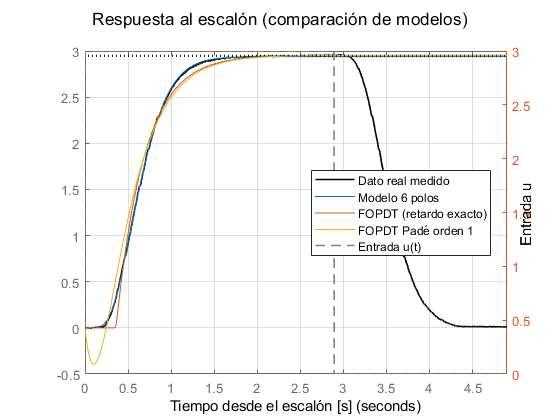


% --- Detectar instante del escalón ---
du = diff(u_escalon);
[~, idx_step] = max(abs(du));   % índice donde ocurre el escalón

% --- Tiempo alineado ---
t0 = t_escalon(idx_step);       % instante real del escalón
t_alineado = t_escalon - t0;    % escalón en t = 0


figure;

% ----------------------------
% EJE IZQUIERDO (y)
% ----------------------------
yyaxis left
plot(t_alineado, y_med_filt, 'k', 'LineWidth', 1.2); 
hold on;

% Dibuja el step en el mismo eje
ax = gca;
step(ax, 3*tf_6polos_escalon_medido, ...
        3*tf_fopdt_medida, ...
        3*tf_fopdt_pade);

% Eliminar título automático de step
title('');

ylabel('Salida y');
grid on;

% ----------------------------
% EJE DERECHO (u)
% ----------------------------
yyaxis right
plot(t_alineado, u_escalon, '--', 'Color',[0.5 0.5 0.5], 'LineWidth', 1.2);
ylabel('Entrada u');

% ----------------------------
% Título propio y etiquetas
% ----------------------------
xlabel('Tiempo desde el escalón [s]');
sgtitle('Respuesta al escalón (comparación de modelos)'); % título general

legend('Dato real medido', ...
       'Modelo 6 polos', ...
       'FOPDT (retardo exacto)', ...
       ['FOPDT Padé orden ' num2str(orden_pade)], ...
       'Entrada u(t)', ...
       'Location','best');

xlim([0 max(t_alineado)]);

## TRANSFERENCIA IDEAL

s = tf('s');
tf_6polos_ideal = 1/(s*0.1 + 1)^6;

## DISEÑO PRBS

En base a los datos medidos de la respueta al escalón, tomamos los siguientes tiempos:

- Tes (tiempo de establecimiento al 5% + retardo) = 1.05 seg (de la respuesta al escalón medido)

- tau (al 63.2%, sin retardo) = 0.33  seg (de la aproximación FOPDT de sysid)

- L = 0.36 seg

***Primer diseño:***

*Elegimos Tmuestreo 10 veces menos que tau*

Tmuestreo = 0.33/10 = 0.033  seg

Definimos Tprbs = Tmuestreo/2 = 0.016 seg

*Calculamos N*

N.Tprbs > (tau + L)

De acá sale N = 0.69/0.016 seg = 43.1 (44 bits) (inviable)

*Calculamos cuando debe durar el ensayo:*

D = Tprbs$\left.{\left(2\right.}^n -1\right)=\;$0.016$\left.{\left(2\right.}^{44} -1\right)=\;$8925.5 años (jajaja)

***Segundo diseño***

*Elegimos Tmuestreo 2 veces menos que tau*

Iterando con distintos valores de N, definimos los Tprbs correspondientes, llegamos a definir la frecuencia de la prbs como el doble de tau. Calculamos la duración del ensayo D.

Tmuestreo = 0.33/2  < 0.165  seg

Definimos Tprbs < Tmuestreo/2 = 0.0825 seg, elegimos 0.065 seg

*Calculamos N*

N.Tprbs > (tau + L)

De acá sale N = 0.69/0.065 seg = 10.6 (11 bits)

N = 11 bits

*Recalculamos Tprbs para  los 11  bits redondeados:*

Tprbs = 65.65 ms

*Calculamos cuando debe durar el ensayo:*

D = 134.283 seg

*Verificamos que en el osciloscopio se pueda medir D a una frecuencia de muestro adecuada*

El osciloscopio utilizado, con base de tiempo de 10 segundos, tiene una frecuencia de muestreo 

de 200 Samples/seg, que cumple que es como mínimo 10 veces mayor que 1/Tprbs = fprbs = 15.23Hz. (13.13 veces mayor).

## DATOS MEDIDOS PRBS REAL

% Importar datos y guardarlos en vectores
datos_prbs = readtable('datos_prbs_medido.CSV');

T_prbs = 1/200;

% Vector salida
y_prbs = datos_prbs.Var2;
y_prbs = (y_prbs - 1000) / 3000;

y_prbs(y_prbs < 0) = 0; % recorto negativos

% Vector entrada
u_prbs = datos_prbs.Var1;
u_prbs(u_prbs < 2500) = 0;
u_prbs(u_prbs >= 2500) = 1;

% Defino el objeto  para el system identification
data_med_prbs = iddata(y_prbs, u_prbs, T_prbs);

% Transferencia que escupe el system identification, 92.35% de coincidencia con
% la otra mitad de los datos
tf_6polos_prbs_medida = tf([5.671618964260604e+05] , [1,58.284099674190490,1.284445491209403e+03,1.622971004687713e+04,1.087898782652298e+05,3.983829952470905e+05,5.775054615523315e+05]);
pole(tf_6polos_prbs_medida) 

ans =  -29.8637 + 0.0000i
  -8.3835 +10.4619i
  -8.3835 -10.4619i
  -4.2178 + 3.9557i
  -4.2178 - 3.9557i
  -3.2177 + 0.0000i


## FOPDT  (PRBS)

Basado en el modelo obtenido en el ensayo de PRBS y del escalón, se obtuvo:


$$\begin{array}{l}
G_{\textrm{FOPDT}} =\frac{K_p e^{-\textrm{Ls}} }{1+\textrm{Ts}}=\frac{\left(0\ldotp 98257\right)e^{-\left(0\ldotp 34639\right)s} }{1+\left(0\ldotp 50484\right)s}\\
T=0\ldotp \\
L=0\\
K_{p\;} =0
\end{array}$$


% Defino el modelo FOPDT y los parámetros del PID
s = tf('s');

K_p = 0.98257

K_p = 0.9826

T = 0.50484 

T = 0.5048

L = 0.34639

L = 0.3464


G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 
tf_fopdt_prbs_medida = G_fopdt;
tf_fopdt_ideal = G_fopdt

tf_fopdt_ideal =
 
                     0.9826
  exp(-0.346*s) * ------------
                  0.5048 s + 1
 
Continuous-time transfer function.



tf_fopdt_prbs_pade = G_sin_retardo*(1-(s*L/2))/(1+(s*L/2));  %  Aproximado por Padé

%% ==========================================
%  COMPARACIÓN: MODELOS PRBS VS RESPUESTA REAL
% ==========================================

% --- Detectar instante del escalón
du = diff(u_escalon);
[~, idx_step] = max(abs(du));
t0 = t_escalon(idx_step);
t_alineado = t_escalon - t0;

% --- Entrada escalón 0->3
u_step = 3 * ones(size(t_alineado));
u_step(t_alineado < 0) = 0;

% --- Simular respuesta al escalón para los modelos PRBS (lsim)
y_step_6polos_prbs = lsim(tf_6polos_prbs_medida, u_step, t_alineado);

y_step_fopdt_prbs  = lsim(tf_fopdt_prbs_medida,  u_step, t_alineado);


% --- Simulación FOPDT con Padé (línea sólida también)
orden_pade_prbs = 1;
[num_pade_prbs, den_pade_prbs] = pade(L, orden_pade_prbs);
tf_fopdt_prbs_pade = G_sin_retardo * tf(num_pade_prbs, den_pade_prbs);
y_step_fopdt_prbs_pade = lsim(tf_fopdt_prbs_pade, u_step, t_alineado);

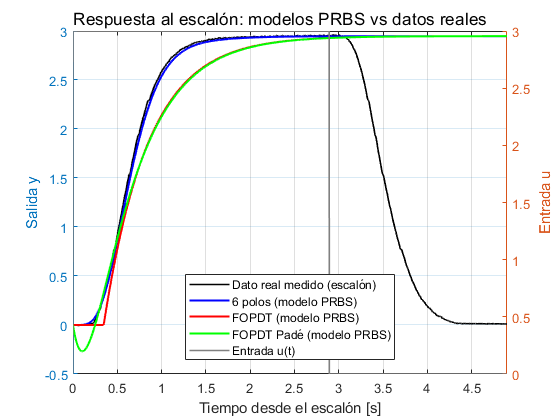


% ==========================================
% CONFIGURACIÓN GLOBAL: LÍNEAS SÓLIDAS
% ==========================================
set(groot, 'defaultLineLineStyle', '-');   % Fuerza líneas sólidas por defecto

% ==========================================
% GRÁFICO FINAL
% ==========================================
figure;

yyaxis left
plot(t_alineado, y_med_filt, 'k-', 'LineWidth', 1.2); hold on;

plot(t_alineado, y_step_6polos_prbs, 'b-', 'LineWidth', 1.5);
plot(t_alineado, y_step_fopdt_prbs, 'r-', 'LineWidth', 1.5);
plot(t_alineado, y_step_fopdt_prbs_pade, 'g-', 'LineWidth', 1.5);

ylabel('Salida y');
grid on;

yyaxis right
plot(t_alineado, u_escalon, 'Color', [0.5 0.5 0.5], 'LineStyle', '-', 'LineWidth', 1.2);
ylabel('Entrada u');

xlabel('Tiempo desde el escalón [s]');
sgtitle('Respuesta al escalón: modelos PRBS vs datos reales');

legend('Dato real medido (escalón)', ...
       '6 polos (modelo PRBS)', ...
       'FOPDT (modelo PRBS)', ...
       'FOPDT Padé (modelo PRBS)', ...
       'Entrada u(t)', ...
       'Location','best');

xlim([0 max(t_alineado)]);

## COMPARACIÓN DE LOS RESULTADOS

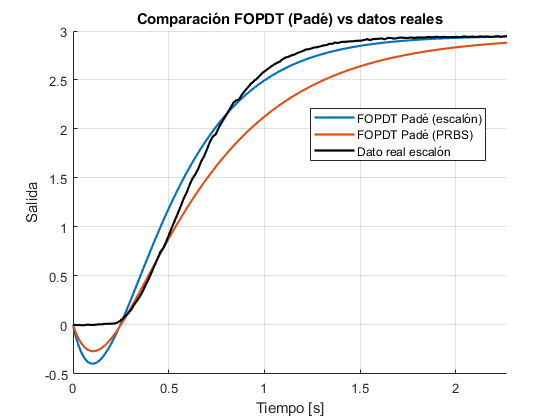

%% =========================
% COMPARACIÓN DE LOS RESULTADOS (FOPDT con Padé)
%% =========================

A = 3;   % amplitud real del escalón

%% Eje temporal común
[y_fopdt_pade_step, t] = step(A * tf_fopdt_pade);

%% Respuesta FOPDT PRBS (Padé)
y_fopdt_prbs_pade = step(A * tf_fopdt_prbs_pade, t);

%% Respuestas 6 polos
y_6polos_step = step(A * tf_6polos_escalon_medido, t);
y_6polos_prbs = step(A * tf_6polos_prbs_medida, t);

%% Interpolar dato real al eje t
y_med_interp = interp1(t_alineado, y_med_filt, t, 'linear', 'extrap');

%% -------------------------
% 1) FOPDT Padé vs dato real
%% -------------------------
figure; grid on; hold on;

plot(t, y_fopdt_pade_step, 'LineWidth', 1.6);
plot(t, y_fopdt_prbs_pade, 'LineWidth', 1.6);
plot(t, y_med_interp,     'k', 'LineWidth', 1.6);

xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación FOPDT (Padé) vs datos reales');
legend('FOPDT Padé (escalón)', ...
       'FOPDT Padé (PRBS)', ...
       'Dato real escalón', ...
       'Location','best');

xlim([0 min(max(t), max(t_alineado))]);
hold off;

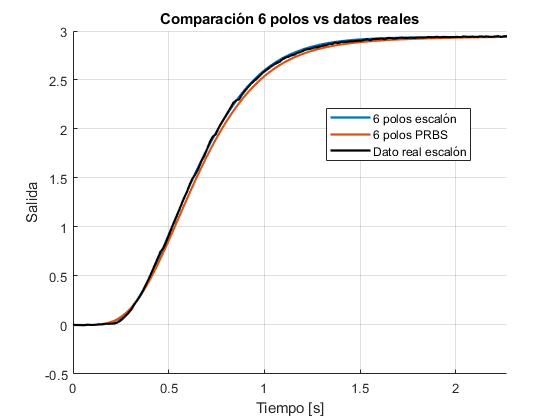


%% -------------------------
% 2) 6 polos vs dato real
%% -------------------------
figure; grid on; hold on;

plot(t, y_6polos_step, 'LineWidth', 1.6);
plot(t, y_6polos_prbs, 'LineWidth', 1.6);
plot(t, y_med_interp, 'k', 'LineWidth', 1.6);

xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación 6 polos vs datos reales');
legend('6 polos escalón', ...
       '6 polos PRBS', ...
       'Dato real escalón', ...
       'Location','best');

xlim([0 min(max(t), max(t_alineado))]);
hold off;

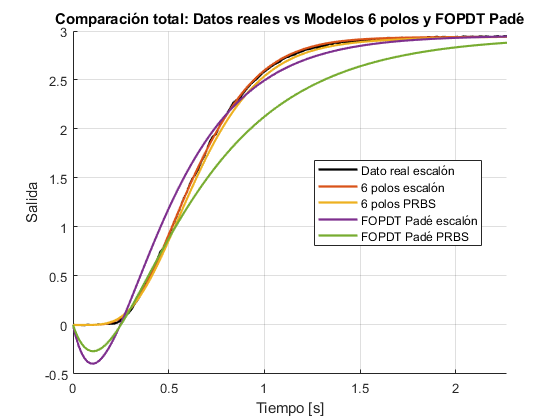


%% =========================
% 3) Comparación total: datos reales + 6 polos + FOPDT Padé
%% =========================

figure; grid on; hold on;

plot(t, y_med_interp,           'k', 'LineWidth', 1.6);

plot(t, y_6polos_step,          'LineWidth', 1.6);
plot(t, y_6polos_prbs,          'LineWidth', 1.6);

plot(t, y_fopdt_pade_step,      'LineWidth', 1.6);
plot(t, y_fopdt_prbs_pade,      'LineWidth', 1.6);

xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación total: Datos reales vs Modelos 6 polos y FOPDT Padé');
legend('Dato real escalón', ...
       '6 polos escalón', ...
       '6 polos PRBS', ...
       'FOPDT Padé escalón', ...
       'FOPDT Padé PRBS', ...
       'Location','best');

xlim([0 min(max(t), max(t_alineado))]);
hold off;

% %% Eje temporal común (tomado del FOPDT medido al escalón)
% [y_fopdt_step, t] = step(tf_fopdt_medida);
% 
% %% Respuestas FOPDT
% y_fopdt_prbs   = step(tf_fopdt_prbs_medida, t);
% y_fopdt_ideal  = step(tf_fopdt_ideal, t);
% 
% %% Respuestas 6 polos
% y_6polos_step  = step(tf_6polos_escalon_medido, t);
% y_6polos_prbs  = step(tf_6polos_prbs_medida, t);
% y_6polos_ideal = step(tf_6polos_ideal, t);
% 
% %% =========================
% % 1) Comparación FOPDT
% %% =========================
% figure; grid on; hold on;
% 
% plot(t, y_fopdt_step,       'LineWidth', 1.6);
% plot(t, y_fopdt_prbs+.01,   'LineWidth', 1.6);
% plot(t, y_med_interp,       'k', 'LineWidth', 1.6);
% 
% xlabel('Tiempo [s]');
% ylabel('Salida');
% title('Comparación modelos FOPDT');
% legend('FOPDT escalón', ...
%        'FOPDT PRBS', ...
%        'Dato medido', ...
%        'Location','best');
% 
% hold off;
% 
% %% =========================
% % 2) Comparación 6 polos
% %% =========================
% figure; grid on; hold on;
% plot(t, y_6polos_step,  'LineWidth', 1.6);
% plot(t, y_6polos_prbs,  'LineWidth', 1.6);
% plot(t, y_6polos_ideal, 'LineWidth', 1.6);
% xlabel('Tiempo [s]');
% ylabel('Salida');
% title('Comparación modelos de 6 polos');
% legend('6 polos escalón','6 polos PRBS','6 polos ideal','Location','best');
% hold off;
% 
% %% =========================
% % 3) Comparación total
% %% =========================
% figure; grid on; hold on;
% plot(t, y_fopdt_step,   'LineWidth', 1.6);
% plot(t, y_fopdt_prbs+0.01,   'LineWidth', 1.6);
% plot(t, y_fopdt_ideal,  'LineWidth', 1.6);
% plot(t, y_6polos_step+.01,  'LineWidth', 1.6);
% plot(t, y_6polos_prbs,  'LineWidth', 1.6);
% plot(t, y_6polos_ideal, 'LineWidth', 1.6);
% xlabel('Tiempo [s]');
% ylabel('Salida');
% title('Comparación total de respuestas al escalón');
% legend( ...
%     'FOPDT escalón', ...
%     'FOPDT PRBS', ...
%     'FOPDT ideal', ...
%     '6 polos escalón', ...
%     '6 polos PRBS', ...
%     '6 polos ideal', ...
%     'Location','best');
% hold off;
% 
% figure; grid on; hold on;
% plot(t, y_6polos_ideal,        'LineWidth', 1.6);
% plot(t, y_fopdt_prbs + 0.01,   'LineWidth', 1.6);
% 
% xlabel('Tiempo [s]');
% ylabel('Salida');
% title('Comparación: 6 polos ideal vs FOPDT PRBS');
% 
% legend( ...
%     '6 polos ideal', ...
%     'FOPDT PRBS', ...
%     'Location','best');
% 
% hold off;


## 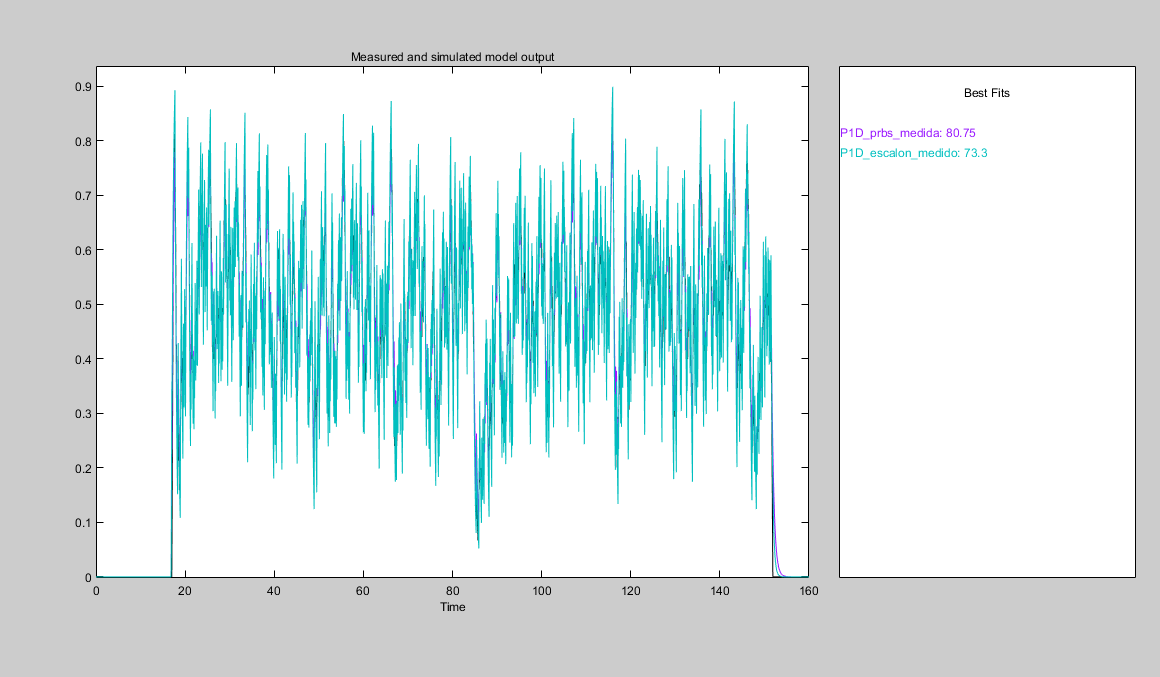

Respuesta a la PRBS de las  transferencias FOPDT de prbs y escalon.